# Лабораторна робота. Медіанний фільтр

Краснопір Тимур, ІПС-32

### Опис алгоритму

Медіанний фільтр застосовують для подавлення імпульсного шуму.

Медіанний фільтр використовує двовимірне вікно (апертура фільтра) для обробки кожної точки зображення. Найчастіше вікно обирають у формі хреста, прямокутника чи квадрата. Вибір форми вікна та розмірів вікна залежить від зображення, до якого застосовують медіанний фільтр. Тобто для кожного зображення вікно (форму та розмір) обирають окремо.

Медіанний фільтр обробляє кожну точку зображення наступним чином.

Нехай `(i, j)` - поточна точка зображення. Для цієї точки медіанний фільтр будує вікно (апертуру фільтра). Потім медіанний фільтр сортує (неважливо за зростанням чи спаданням) всі ті точки зображення, що потрапили у це вікно. Та точка зображення, що займає центральне положення (за індексом) у цій відсортованій послідовності, буде медіаної цієї послідовності. Значення медіани буде присвоєно точці `(i, j)`.

Нижче наведено приклад вікна у формі квадрата (3х3), відсортана послідовність та медіана цієї послідовності. Значення 186 (медіана) буде присвоєно точці зі значенням 161 (це поточна точка зображення).

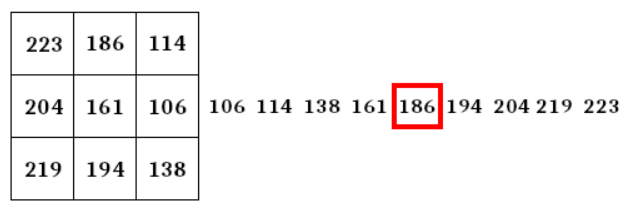

(приклад взят з [https://docs.gimp.org/2.10/ru/gimp-filter-median-blur.html](https://docs.gimp.org/2.10/ru/gimp-filter-median-blur.html))

Медіанний фільтр обробляє кожну точку зображення, але щодо граничних точок зображення існують наступні підходи (наведено деякі з них):

- Не обробляти граничні точки зображення.

- На час обробки зображення додавати до нього необхідну кількість точок зі значенням 0. Приклад наведено нижче.

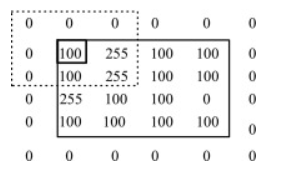

(взято з [https://www.sciencedirect.com/topics/computer-science/median-filter](https://www.sciencedirect.com/topics/computer-science/median-filter))

### Приклади застосування медіанного фільтра

#### Приклад 1 (`saturn2.gif`)

Зчитаємо зображення з графічного файлу `saturn2.gif`.

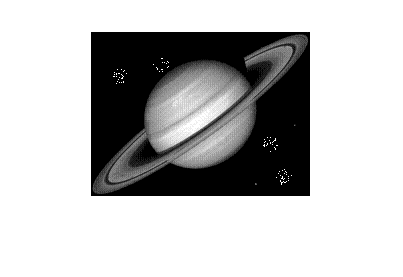

originalImage = imread('saturn2.gif');
imshow(originalImage);

Для того, аби прибрати імпульсний шум з наведеного вище зображення, застосуємо до цього зображення медіанний фільтр.

Оберемо медіанний фільтр з вікном у формі прямокутника.

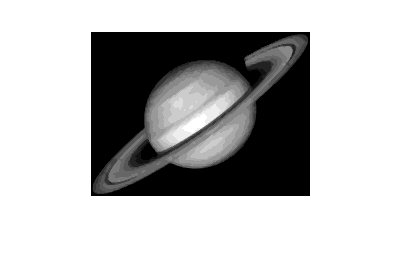

filteredImage = applyRectangleMedianFilter(originalImage, 3, 3);
imshow(filteredImage);

А тепер оберемо медіанний фільтр з вікном у формі хреста.

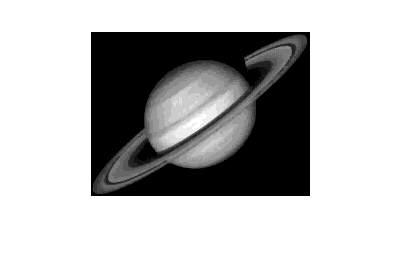

filteredImage = applyCrossMedianFilter(originalImage, 3, 4);
imshow(filteredImage);

Бачимо, що для початкового зображення `saturn2.gif` краще обрати медіанний фільтр з вікном у формі хреста, бо тоді чіткість зображення буде збережена краще.

#### Приклад 2 (`saturn3.gif`)

Зчитаємо зображення з графічного файлу `saturn3.gif`.

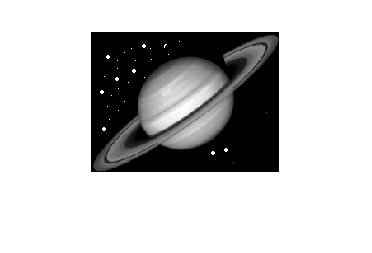

originalImage = imread('saturn3.gif');
imshow(originalImage);

Для того, аби прибрати імпульсний шум з наведеного вище зображення, застосуємо до цього зображення медіанний фільтр.

Оберемо медіанний фільтр з вікном у формі прямокутника.

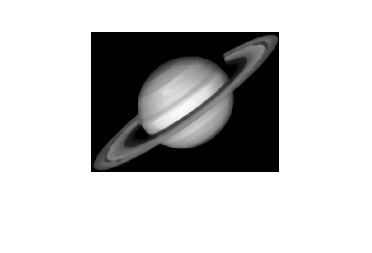

filteredImage = applyRectangleMedianFilter(originalImage, 4, 5);
imshow(filteredImage);

А тепер оберемо медіанний фільтр з вікном у формі хреста.

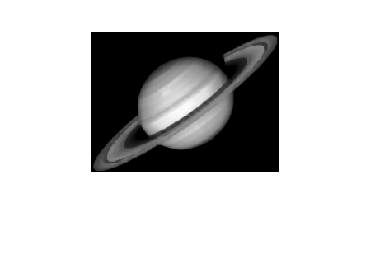

filteredImage = applyCrossMedianFilter(originalImage, 5, 6);
imshow(filteredImage);

Бачимо, що для початкового зображення `saturn3.gif` краще обрати медіанний фільтр з вікном у формі хреста, бо тоді чіткість зображення буде збережена краще.

### Реалізація (код) медіанного фільтра

Наведені нижче функції `applyRectangleMedianFilter` та `applyCrossMedianFilter` для обробки граничних точок зображення додають до зображення на час обробки необхідну кількість точок зі значенням 0 (див. підходи щодо обробки граничних точок зображення).

`The window of this 2D median filter is a rectangle (a matrix which has 'numOfRows' rows and 'numOfColumns' columns).`

`This function supposes 'numOfRows' and 'numOfColumns' to be positive integers (not necessarily the same).`

function filteredImage = applyRectangleMedianFilter(originalImage, numOfRows, numOfColumns)
    offsetX = numOfColumns - ceil(numOfColumns / 2);
    offsetY = numOfRows - ceil(numOfRows / 2);
    
    differenceOffsetX = 0;
    differenceOffsetY = 0;
    
    if rem(numOfColumns, 2) == 0
        differenceOffsetX = 1;
    end
    
    if rem(numOfRows, 2) == 0
        differenceOffsetY = 1;
    end
    
    filteredImage = zeros(size(originalImage, 1) + 2 * offsetY - differenceOffsetY, size(originalImage, 2) + 2 * offsetX - differenceOffsetX, class(originalImage));
    filteredImage(ceil(numOfRows / 2):(end - offsetY), ceil(numOfColumns / 2):(end - offsetX)) = originalImage;
    
    for i = ceil(numOfRows / 2):(size(filteredImage, 1) - offsetY)
        for j = ceil(numOfColumns / 2):(size(filteredImage, 2) - offsetX)
            % the window
            rectangle = filteredImage((i - (offsetY - differenceOffsetY)):(i + offsetY), (j - (offsetX - differenceOffsetX)):(j + offsetX));
            
            v = reshape(rectangle, 1, []);
            v = sort(v);
            
            middleIndex = ceil(size(v, 2) / 2);
            filteredImage(i, j) = v(middleIndex);
        end
    end
    
    filteredImage = filteredImage(ceil(numOfRows / 2):(size(filteredImage, 1) - offsetY), ceil(numOfColumns / 2):(size(filteredImage, 2) - offsetX));
end

`The window of this 2D median filter is a cross.`

`The cross has the 'crossHeight' height and the 'crossWidth' width.`

`This function supposes 'crossHeight' and 'crossWidth' to be positive integers (not necessarily the same).`

function filteredImage = applyCrossMedianFilter(originalImage, crossHeight, crossWidth)
    offsetX = crossWidth - ceil(crossWidth / 2);
    offsetY = crossHeight - ceil(crossHeight / 2);
    
    differenceOffsetX = 0;
    differenceOffsetY = 0;
    
    if rem(crossWidth, 2) == 0
        differenceOffsetX = 1;
    end
    
    if rem(crossHeight, 2) == 0
        differenceOffsetY = 1;
    end
    
    filteredImage = zeros(size(originalImage, 1) + 2 * offsetY - differenceOffsetY, size(originalImage, 2) + 2 * offsetX - differenceOffsetX, class(originalImage));
    filteredImage(ceil(crossHeight / 2):(end - offsetY), ceil(crossWidth / 2):(end - offsetX)) = originalImage;
    
    for i = ceil(crossHeight / 2):(size(filteredImage, 1) - offsetY)
        for j = ceil(crossWidth / 2):(size(filteredImage, 2) - offsetX)
            % the elements on the cross's horizontal line including the (i, j)
            horizontal = filteredImage(i, (j - (offsetX - differenceOffsetX)):(j + offsetX));
            
            % the elements on the cross's vertical line above the (i, j) (not including (i, j))
            above = transpose(filteredImage((i - (offsetY - differenceOffsetY)):(i - 1), j));
            
            % the elements on the cross's vertical line below the (i, j) (not including (i, j))
            below = transpose(filteredImage((i + 1):(i + offsetY), j));
            
            cross = [horizontal above below]; % the window
            cross = sort(cross);
            
            middleIndex = ceil(size(cross, 2) / 2);
            filteredImage(i, j) = cross(middleIndex);
        end
    end
    
    filteredImage = filteredImage(ceil(crossHeight / 2):(size(filteredImage, 1) - offsetY), ceil(crossWidth / 2):(size(filteredImage, 2) - offsetX));
end